Group 5:

Tikhon Riazantsev, Agastya Heryudhanto, Tabea Volpert, 

Nadja Rothberg.

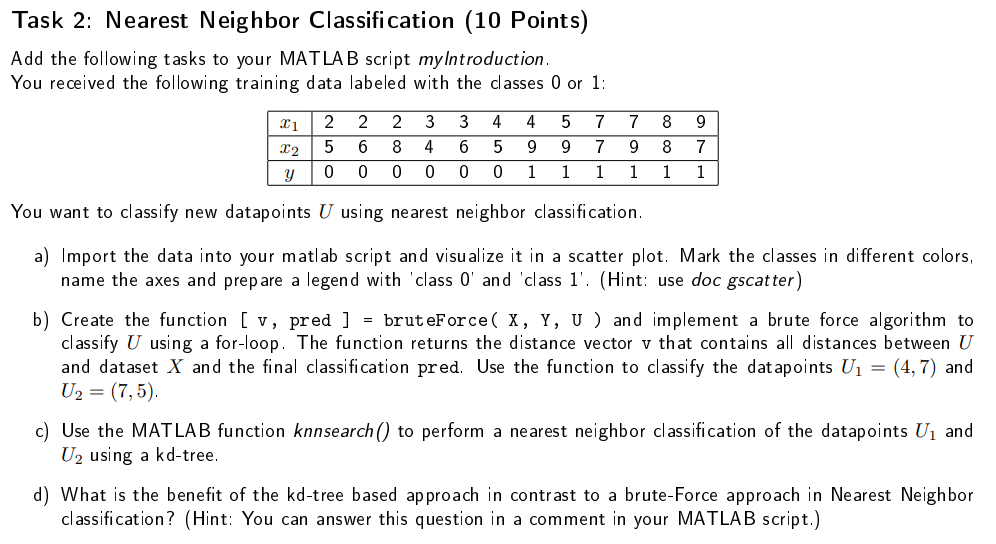

a)

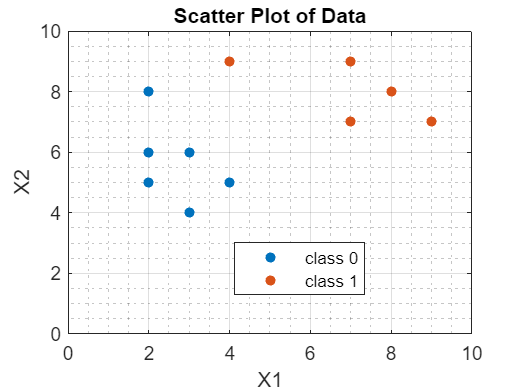

close all;
clear;
x1 = [2; 2; 2; 3; 3; 4; 4; 4; 7; 7; 8; 9];
x2 = [5; 6; 8; 4; 6; 5; 9; 9; 7; 9; 8; 7];
Y = [0; 0; 0; 0; 0; 0; 1; 1; 1; 1; 1; 1];
f1 = figure;
scatterplot = gscatter(x1,x2,Y);
xlabel('X1');
ylabel('X2');
legend('class 0', 'class 1', "Position",...
    [0.45,0.25,0.25,0.13]);
title('Scatter Plot of Data');
grid on;
grid minor;
xlim([0, 10]);
ylim([0, 10]);

b)

X = [2 2; 2 3; 2 4; 3 4; 3 5; 4 5; 4 9; 5 9; 7 7;...
    7 9; 8 8; 9 7];
U1 = [4, 7];
U2 = [7, 5];

[v1, pred1] = bruteForce(X, Y, U1);
[v2, pred2] = bruteForce(X, Y, U2);

fprintf('U1 (%d, %d), is classified as class %d\n', ...
    U1(1), U1(2), pred1);

U1 (4, 7), is classified as class 0


fprintf('U2 (%d, %d), is classified as class %d\n', ...
    U2(1), U2(2), pred2);

U2 (7, 5), is classified as class 1


с)

kdtree = createns(X, 'NSMethod', 'kdtree');

idx_U1 = knnsearch(kdtree, U1, 'K', 1);
idx_U2 = knnsearch(kdtree, U2, 'K', 1);

class_U1 = Y(idx_U1);
class_U2 = Y(idx_U2);ass_U2 = Y(idx_U2(1));

fprintf('U1 (%d, %d) is classified as class %d\n', ...
    U1(1), U1(2), class_U1);

U1 (4, 7) is classified as class 0


fprintf('U2 (%d, %d) is classified as class %d\n', ...
    U2(1), U2(2), class_U2);

U2 (7, 5) is classified as class 1


d)

time_bruteforce = timeit(@() bruteForce(X, Y, U1));
time_knnsearch = timeit(@() knnsearch(kdtree, U1, 'K', 1));
fprintf('Time to classify for bruteForce classifier: %s\n', ...
    time_bruteforce);

Time to classify for bruteForce classifier: 6.467100e-06


fprintf('Time to classify for knnsearch classifier: %s\n', ...
    time_knnsearch);

Time to classify for knnsearch classifier: 3.701710e-05


fprintf(['As we can see, knnsearch is slower in classifying small' ...
    'datasets, but much faster in larger ones.\n' ...
    'If we are classifying data with n dimensions and m samples' ...
    'Time to compute of knnsearch is O(nlog(m))\n' ...
    'Time to compute bruteForce is O(nm)'])

As we can see, knnsearch is slower in classifying smalldatasets, but much faster in larger ones.
If we are classifying data with n dimensions and m samplesTime to compute of knnsearch is O(nlog(m))
Time to compute bruteForce is O(nm)